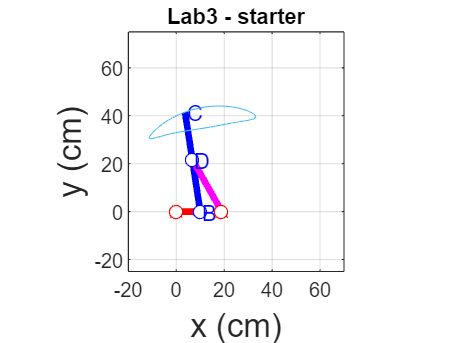

%%% MIE301 Lab 3: Optimizing mechanisms
%% part a
close all; % closes all figures
clear all; % clears all variables from memory
clc;       % clears all calculations from the Matlab workspace

% Plot Parameters: these will be used to set the axis limits on the figure
xmin= -20; % leftmost window edge
xmax= 70;  % rightmost window edge
ymin= -25; % bottom window edge
ymax= 75;  % top window edge

% Link Parameters
increments = 100; % number of theta2 configuration steps to calculate along mechanism rotation %%%% YOU MAY WANT TO CHANGE THIS

max_rotation_theta2 = 360 *pi/180; % rotation limit of theta2, radians
theta2 = linspace(0,max_rotation_theta2,increments); % link 2 rotation into 'increments' number of angles

r1 = 19;          % link 1 length, cm
r2 = 10;          % link 2 length, cm
r3 = 22;          % link 3 length, cm
r4 = 25;          % link 4 length, cm
re=20;            % extension length, cm
a = 0.1 ;         % path slope tolerance 
% Rotation time
theta2_dot = 60;                        % rotation rate, rpm
t_rev = 60/theta2_dot;                  % rotation time limit, seconds
time = linspace(0,t_rev,increments);    % link 2 rotation into 'increments' number of times

% set up figure
figure(1);                         %create new figure
set(1,'WindowStyle','Docked')      %dock the figure
% 4-bar mechanism geometric constants: See textbook section 4.3.3 for derivation. (Eq. 4.3-54)

% Hint: add a for-loop here to calculate mechanism motion and plot iterate over r3
% recommended range for r3 20:0.5:30
h1 = r1/r2;
h2 = r1/r3;
h3 = r1/r4;
h4 =(-r1^2-r2^2-r3^2+r4^2)/(2*r2*r3);
h5 =(r1^2+r2^2-r3^2+r4^2)/(2*r2*r4);
    for i=1:increments                        % step through motion of the mechanism
        hold off;

        %  geometric calculations (book eq. 4.3-56 to 4.3-62):
        d = -h1 +(1-h3)*cos(theta2(i)) +h5;
        b = -2*sin(theta2(i));
        e = h1 -(1+h3)*cos(theta2(i)) +h5;
        a_a = -h1 +(1+h2)*cos(theta2(i)) +h4;
        c = h1 -(1-h2)*cos(theta2(i)) +h4;

        theta3_1(i) = 2*atan(((-b-(b^2-4*a_a*c)^0.5)/(2*a_a))); %calculate angle of link 3 (eq. 4.3-64)
        theta4_1(i) = 2*atan(((-b-(b^2-4*d*e)^0.5)/(2*d)));          

        % Link Coordinates calculations:   
        Ax(i) = 0;                                      % pivot point of link 2 position
        Ay(i) = 0;                                      % pivot point of link 2 position
        Bx(i) = r2*cos( theta2(i) );                    % point B position
        By(i) = r2*sin( theta2(i) );                    % point B position
        Cx(i,1) = Bx(i) + (r3+re )*cos( theta3_1(i) );             % point C position. We're going to store these for each extension value (indexed by j)
        Cy(i,1) = By(i) + (r3+re )*sin( theta3_1(i) );             % point C position
        Dx(i) = r1 + r4*cos( theta4_1(i) );             % point D position
        Dy(i) = r4*sin( theta4_1(i) );                  % point D position        
        
        if (true) % put true here to draw the mechanism each time, false to skip drawing that for increased simulation speed
            plot( [Ax(i) Bx(i)], [Ay(i), By(i)],'Color','r','LineWidth',3 ); % draw link2
            hold on;            
            plot( [Bx(i), Dx(i)], [ By(i), Dy(i)],'Color','b','LineWidth',3 ); % draw link3
            plot( [Dx(i), Cx(i,1)], [ Dy(i), Cy(i,1)],'Color','b','LineWidth',3 ); % draw link3 extension to point C
            plot( [r1, Dx(i)], [ 0, Dy(i)],'Color','m','LineWidth',3 ); % draw link4
            
            % Draw Base Pivots:
            recsz = 2.5;                                        % size of drawn base pivot
            plot([0,recsz],[0,-recsz],'r');                     % draw base pivot for link2
            plot([0,-recsz],[0,-recsz],'r');                    % draw base pivot for link2
            plot(0,0,'ro','MarkerFaceColor','w');               % draw a small circle at the base pivot point
            plot(Bx(i), By(i), 'bo','MarkerFaceColor','w');     % draw a small circle at B
            text(Bx(i)+0.9, By(i), 'B','color','b');            % label point B

            plot([r1,r1+recsz],[0,-recsz],'r');                 % draw base pivot for link4
            plot([r1,r1-recsz],[0,-recsz],'r');                 % draw base pivot for link4
            plot(r1,0,'ro','MarkerFaceColor','w');              % draw a small circle at the base pivot point
            plot(Dx(i), Dy(i), 'bo','MarkerFaceColor','w');     % draw a small circle at D
            text(Dx(i)+0.9, Dy(i), 'D','color','b');            % label point D
            text(Cx(i,1)+0.9, Cy(i,1), 'C','color','b');        % label point C
            
            xlabel('x (cm)', 'fontsize', 15);   % axis label
            ylabel('y (cm)', 'fontsize', 15);   % axil label 
            title('Lab3 - starter');            % add a title to the figure
            axis equal;                         % make sure the figure is not stretched
            grid on;
            axis( [xmin xmax ymin ymax] );      % figure axis limits            
        end
        pause(0.1);                            % wait to proceed to next configuration, seconds
    end        
     pause(.01); %pause after drawing the current and previous paths, seconds



% compute slope on point c path
for i=1:1:length(Cx)
    if i==1
    s(i)=(Cy(2)-Cy(end))/(Cx(2)-Cx(end));
    elseif i==length(Cx)
    s(i)=(Cy(1)-Cy(end-1))/(Cx(1)-Cx(end-1));
    else
    s(i)=(Cy(i+1)-Cy(i-1))/(Cx(i+1)-Cx(i-1));
    end
end
% get the very left and right points on point c path
index_left=find(Cx==max(Cx));
index_right=find(Cx==min(Cx));

k = find(abs(s) < a); % find the poins with slope smaller than a
k_bottom=k(k<index_right & k>index_left);% select the points at the bottom of the path

% compute length of straight portion

g=0;
k_start=k_bottom(1);
k_end=k_bottom(end);
for j=k_start:1:k_end-1
    g_=((Cx(j+1)-Cx(j))^2+(Cy(j+1)-Cy(j))^2)^0.5;
    g=g+g_;
end

% plot the point c path
plot(Cx,Cy)


% todo: plot g as function r3





%% part b - Plot the optimized trace; with the straight line portion precisely marked. 
% Include the optimized mechanism links. 
% first find the max g and its corresponding r3

%% part c - Input link angle?





%% part d - Max and min speed and acceleration of the trace point C through the straight portion? 
% Hint: distance between C(i+1) and C(i-1) devided by 2 delta_t can give
% you an approximation of speed at point C(i)
% acceleration = change in speed/change in time



%% part e - How does the tolerance (a) affect your optimized path length? 

% Hint: Similar to part a,but add an outer loop and iterate over a instead of r3
